% Model A

aH_in = rtcpjd(66.6, 0, 0); % new incoming event max 15 times/ second
aN_in = rtcpjd(1000, 0, 0); % new incoming event max every s -> every 1000 ms
b1_in = rtcfs(4); % 4000 resources (instructions) per time unit interval (millisecond) CHANGE
b2_in = rtctdma(8,10,10); % 8/10 slots of the bus -> rest is needed for idle
b3_in = rtcfs(4);

% computation and communication demands e
e1 = 100 + 100; % # instructions needed (/1000) CHANGE
e2 = 1000;
e3 = 160; % 20 * 8 bits need to be transfered using the bus
e4 = 100;

[aH_out, b3_out1, del1, buf1] = rtcgpc(aH_in, b3_in, e1);
[aN_out1, b1_out, del2, buf2] = rtcgpc(aN_in, b1_in, e2);
[aN_out2, b2_out, del3, buf3] = rtcgpc(aN_out1, b2_in, e3);
[aN_out3, b3_out2, del4, buf4] = rtcgpc(aN_out2, b3_out1, e4);

% plotting
disp(['a_{Helligkeit, in}']);

a_{Helligkeit, in}


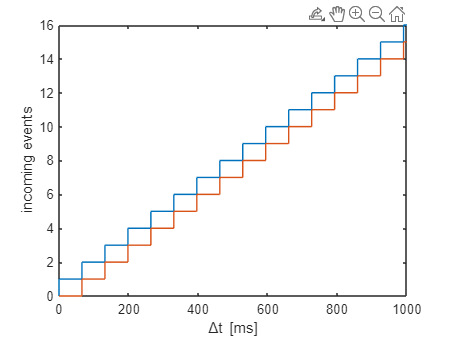

rtcplot(aH_in, 1000);
xlabel('\Deltat [ms]');
ylabel('incoming events'); % brightness control

%legend('upper','lower');
disp(['a_{Helligkeit, out}']);

a_{Helligkeit, out}


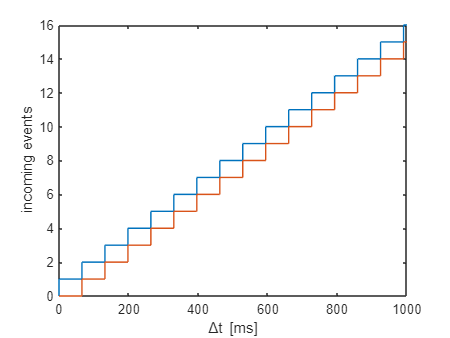

rtcplot(aH_out, 1000);
xlabel('\Deltat [ms]');
ylabel('incoming events');


disp(['a_{Nachricht, in}']);

a_{Nachricht, in}


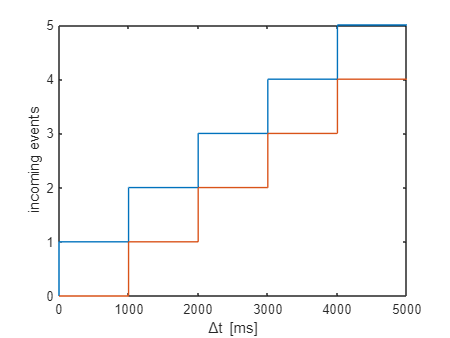

rtcplot(aN_in, 5000);
xlabel('\Deltat [ms]');
ylabel('incoming events'); % receiving message

disp(['a_{Nachricht, out}']);

a_{Nachricht, out}


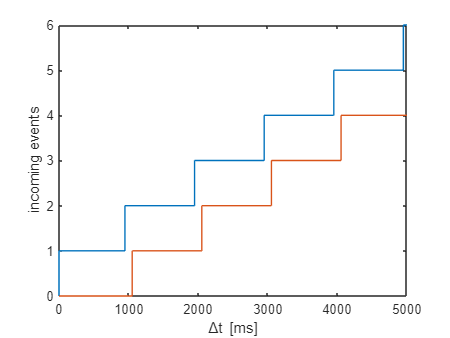

rtcplot(aN_out3, 5000);
xlabel('\Deltat [ms]');
ylabel('incoming events');


disp(['b1_{in}']);

b1_{in}


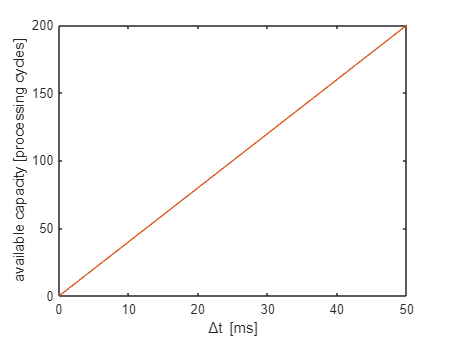

rtcplot(b1_in, 50);
xlabel('\Deltat [ms]');
ylabel('available capacity [processing cycles]');

disp(['b1_{out}']);

b1_{out}


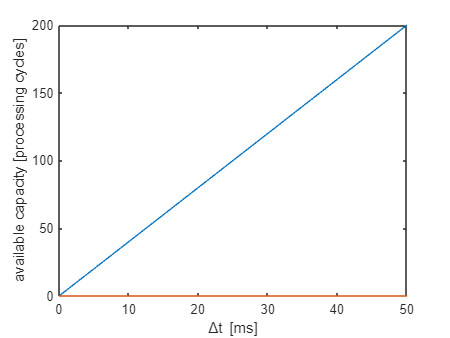

rtcplot(b1_out, 50);
xlabel('\Deltat [ms]');
ylabel('available capacity [processing cycles]');


disp(['b2_{in}']);

b2_{in}


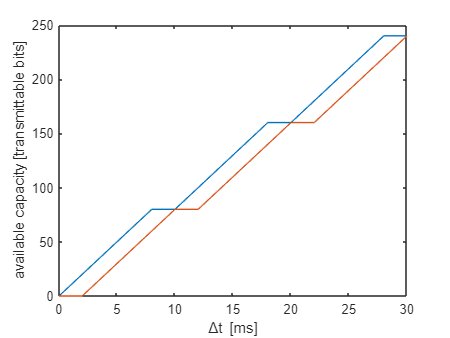

rtcplot(b2_in, 30);
xlabel('\Deltat [ms]');
ylabel('available capacity [transmittable bits]');

disp(['b2_{out}']);

b2_{out}


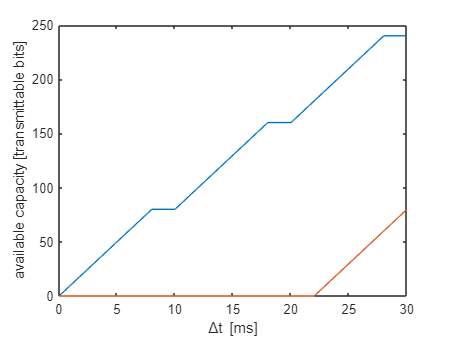

rtcplot(b2_out, 30);
xlabel('\Deltat [ms]');
ylabel('available capacity [transmittable bits]');


disp(['b3_{in}']);

b3_{in}


rtcplot(b3_in, 50);
xlabel('\Deltat [ms]');
ylabel('available capacity [processing cycles]');

disp(['b3_{out}']);

b3_{out}


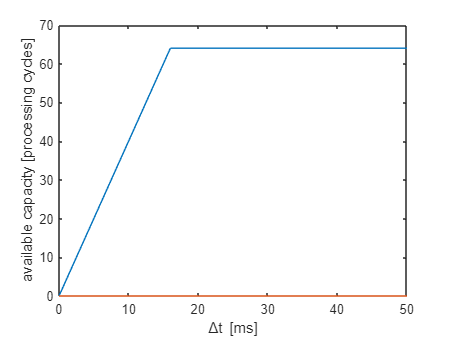

rtcplot(b3_out2, 50);
xlabel('\Deltat [ms]');
ylabel('available capacity [processing cycles]');



disp(['delay a_{Helligkeit} = ', num2str(del1)]);

delay a_{Helligkeit} = 50


delayLoose = del2 + del3 + del4;
delayTight = rtcdel(aN_in, b1_in, e2, b2_in, e3, b3_out1, e4);
disp(['delay a_{Nachricht} loosely = ', num2str(delayLoose), '; delay a_{Nachricht} tighter = ', num2str(delayTight)]);

delay a_{Nachricht} loosely = 395; delay a_{Nachricht} tighter = 395



bufferLoose = buf1 + buf2 + buf3 + buf4;
bufferTight = buf1 + rtcbuf(aN_in, b1_in, e2, b2_in, e3, b3_out1, e4);
disp(['buffer loosely = ', num2str(bufferLoose), '; buffer tighter = ', num2str(bufferTight)]);

buffer loosely = 4; buffer tighter = 2


% USE AS EXAMPLE in Präsi: tighter bounds mgl.

% ---------- MODEL B ----------------------

bB_in = rtcfs(5);

[aH_out, b_out1, del1, buf1] = rtcgpc(aH_in, bB_in, e1);
[aN_out, b_out2, del2, buf2] = rtcgpc(aN_in, b_out1, (e2+e4));

% plotting
disp(['b_{in}']);

b_{in}


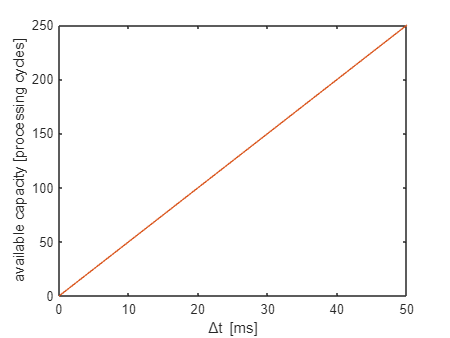

rtcplot(bB_in, 50);
xlabel('\Deltat [ms]');
ylabel('available capacity [processing cycles]');

disp(['b_{out}']);

b_{out}


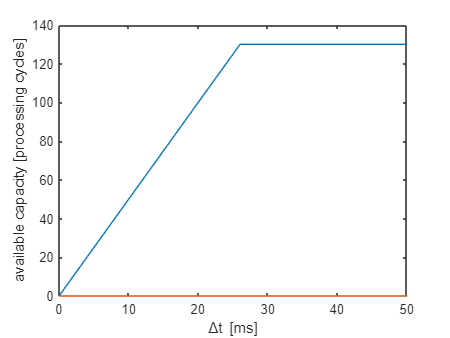

rtcplot(b_out2, 50);
xlabel('\Deltat [ms]');
ylabel('available capacity [processing cycles]');


disp(['delay a_{Helligkeit} = ', num2str(del1)]);

delay a_{Helligkeit} = 40


disp(['delay a_{Nachricht} = ', num2str(del2)]);

delay a_{Nachricht} = 580



bufferL = buf1 + buf2;
disp(['buffer loosely = ', num2str(bufferL)]);

buffer loosely = 2
